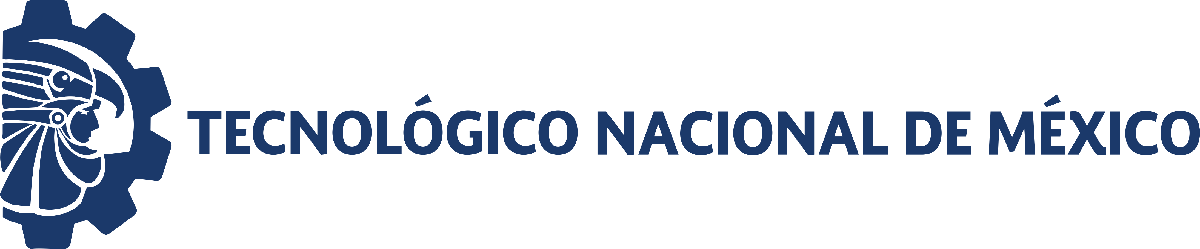                                 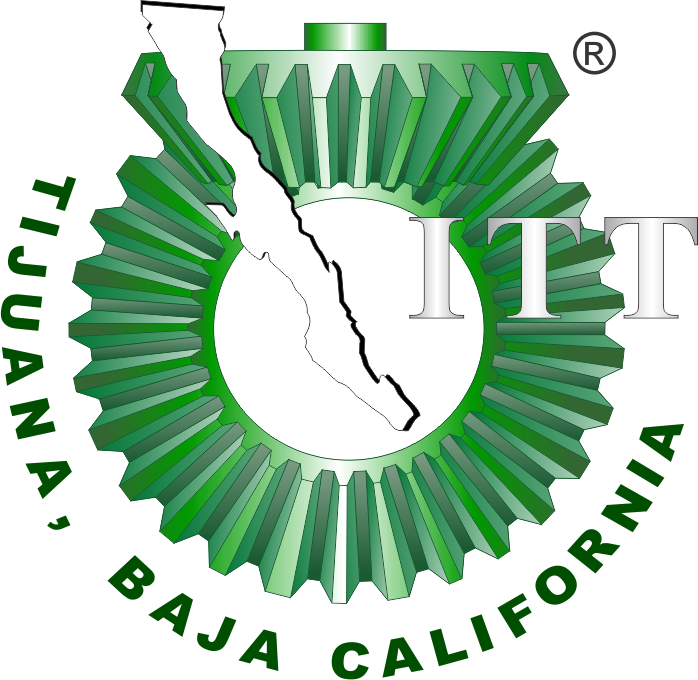

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

# Práctica 1: Sistema presa-depredador de Lotka-Volterra

**Objetivo. ** Aplicar el sistema de Lotka-Volterra para analizar los datos registrados en la interacción de dos especies articas, liebres (presa) y linces (depredador) durante 20 años. El sistema presa-depredador se formula mediante las siguientes dos EDOs de primer orden:


$$\dot x = \alpha x - \beta xy
$$



$$\dot y = \delta xy - \gamma y$$


donde los valores de los parámetros $\alpha$,$\beta ,$$\delta ,$$\gamma >0$, y las condiciones iniciales $x\left(0\right),$$y\left(0\right)>0$.

***[Figura representativa del sistema elaborada en BioRender] ***

Figura. Generar la figura del sistema presa-depredador con [https://bioart.niaid.nih.gov/](https://bioart.niaid.nih.gov/) o [https://www.biorender.com/](https://www.biorender.com/).

## Referencias

[1] Valle, Paul A., Syllabus para Biología de Sistemas y Gemelos Digitales, Tecnológico Nacional de México / Instituto Tecnológico de Tijuana, Tijuana, B.C., México, 2026. Permalink: [https://biomath.xyz/course/](https://biomath.xyz/course/) 

[2] Garfinkel, Alan, Jane Shevtsov, and Yina Guo. Modeling life: the mathematics of biological systems. Springer International Publishing AG, 2017.

## Información general

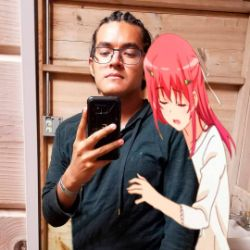

***[Foto 250x250]***

Nombre del alumno: **Nestor Roman Valadez Madera**

Número de control: **m26210087**

Correo institucional: **m26210087**@**tectijuana.edu.mx**

Asignatura: **Modelado Matemático**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## **Datos Experimentales**

clc; close all; warning('off', 'all')

## Datos Crudos

file = 'data.csv'; smooth = false; normalize = false;
[t,x,y] = getdata(file, smooth, normalize);
figname = 'Crudos';
%plotsys(t,x,y, figname, normalize)
mdl = fitmodel(t, x, y, [0.5; 2/max(y); 2/max(x); 1], true);


-----Bioestadisticos-----
Cantidad de datos: 42
Catidad de parametros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.05

Relacion n/k<40 para el calculo del AICc: 10.500

    Parameters      Estimate         SE           MoE                  CI95                Pvalue  
    ___________    __________    __________    __________    ________________________    __________

    {["alfa" ]}       0.54491      0.023095      0.046754       0.49815       0.59166    2.6757e-24
    {["beta" ]}    2.7681e-06    1.6534e-07    3.3472e-07    2.4334e-06    3.1029e-06    3.9615e-19
    {["delta"]}    2.6486e-06    1.1704e-07    2.3693e-07    2.4117e-06    2.8855e-06    1.1783e-23
    {["gamma"]}       0.84639      0.038254      0.0774

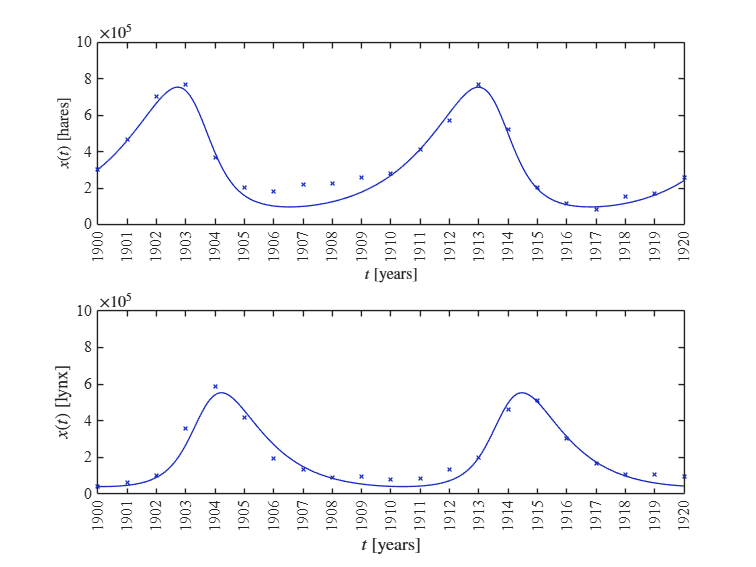

par = table2array(mdl.Coefficients(:,1));

alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
save('parameters.mat', 'alpha', 'beta', 'delta', 'gamma');
[ta, xa, ya] = LotkaVolterra(par, t, x(1), y(1));
plotfitting(t, x, y, ta, xa, ya, figname, normalize)

## Datos Normalizados

file = 'data.csv'; smooth = false; normalize = true;
[t,x,y] = getdata(file, smooth, normalize);
figname = 'Normalizados';
%plotsys(t,x,y, figname, normalize)
mdl = fitmodel(t, x, y, [1; 1; 1; 1], true);


-----Bioestadisticos-----
Cantidad de datos: 42
Catidad de parametros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.05

Relacion n/k<40 para el calculo del AICc: 10.500

    Parameters     Estimate       SE         MoE              CI95             Pvalue  
    ___________    ________    ________    ________    __________________    __________

    {["alfa" ]}    0.55468     0.025414    0.051449    0.50323    0.60613    4.2356e-23
    {["beta" ]}      1.658     0.097213      0.1968     1.4612     1.8548    2.1231e-19
    {["delta"]}     2.0217     0.096219     0.19478     1.8269     2.2165    1.6123e-22
    {["gamma"]}    0.82794     0.039321    0.079601    0.74834    0.90754     1.497e-22


-----Criterios de bondad 

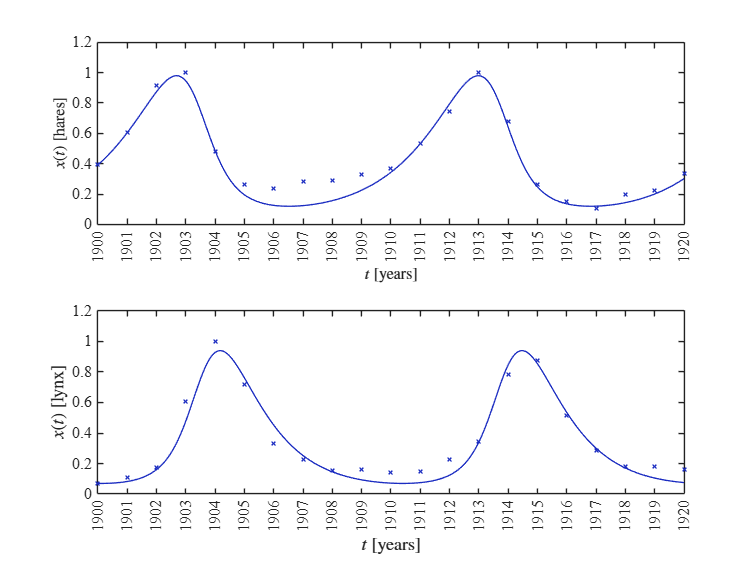

par = table2array(mdl.Coefficients(:,1));
[ta, xa, ya] = LotkaVolterra(par, t, x(1), y(1));
plotfitting(t, x, y, ta, xa, ya, figname, normalize)

### Desnormalizacion de los parametros

file = 'data.csv'; smooth = false; normalize = false;
[t,x,y] = getdata(file, smooth, normalize);
par(2) = par(2)/max(y);
par(3) = par(3)/max(x);
fprintf('alpha: %.3e, beta %.3e, delta: %.3e, gamma: %.3e', par(1), par(2), par(3), par(4))

alpha: 5.547e-01, beta 2.816e-06, delta: 2.628e-06, gamma: 8.279e-01

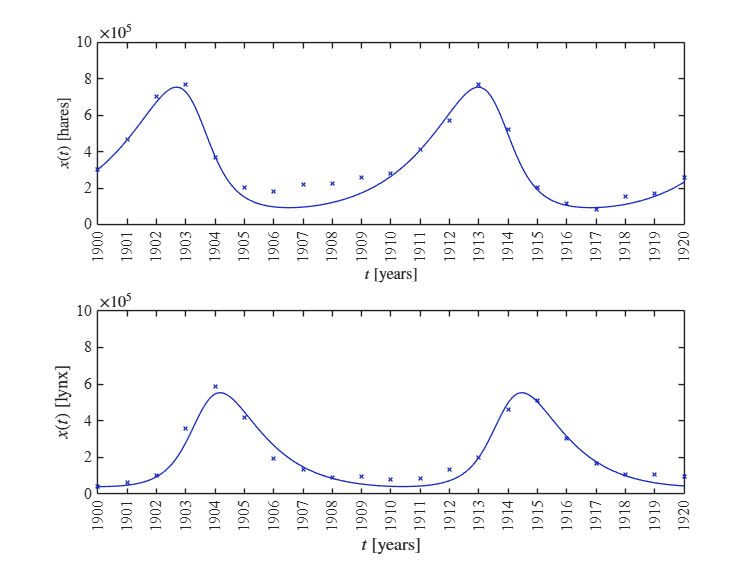

[ta, xa, ya] = LotkaVolterra(par, t, x(1), y(1));
figname = 'unnormalized';
plotfitting(t, x, y, ta, xa, ya, figname, false)

## Datos Suavizados

file = 'data.csv'; smooth = true; normalize = false;
[t,x,y] = getdata(file, smooth, normalize);
figname = 'Suavizados';
%plotsys(t,x,y, figname, normalize);
mdl = fitmodel(t, x, y, [0.5; 1/max(y); 2/max(x); 1], true);


-----Bioestadisticos-----
Cantidad de datos: 42
Catidad de parametros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.05

Relacion n/k<40 para el calculo del AICc: 10.500

    Parameters      Estimate         SE           MoE                  CI95                Pvalue  
    ___________    __________    __________    __________    ________________________    __________

    {["alfa" ]}       0.40072      0.019794       0.04007       0.36065       0.44079    5.9115e-22
    {["beta" ]}    2.1435e-06    1.3084e-07    2.6487e-07    1.8786e-06    2.4084e-06    8.1836e-19
    {["delta"]}    2.8888e-06      1.37e-07    2.7733e-07    2.6114e-06    3.1661e-06    1.4225e-22
    {["gamma"]}        1.0037      0.049747       0.100

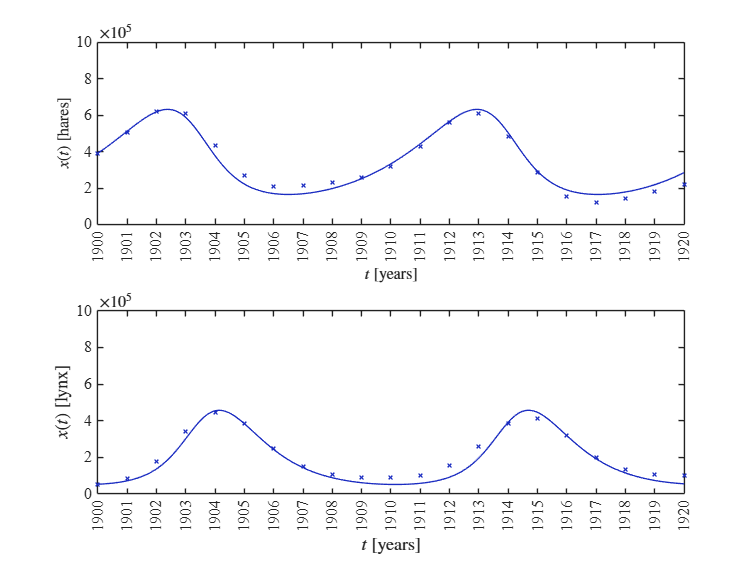

par = table2array(mdl.Coefficients(:,1));
[ta, xa, ya] = LotkaVolterra(par, t, x(1), y(1));
plotfitting(t, x, y, ta, xa, ya, figname, normalize)

## Datos Suavizados y Normalizados

file = 'data.csv'; smooth = true; normalize = true;
[t,x,y] = getdata(file, smooth, normalize);
figname = 'smoothnormalized';
mdl = fitmodel(t, x, y, [1; 1; 1; 1], true);


-----Bioestadisticos-----
Cantidad de datos: 42
Catidad de parametros: 4
Grados de libertad: 38
Valor t-student: 2.024
Valor de significancia (alfa) para los intervalos de confianza: 0.05

Relacion n/k<40 para el calculo del AICc: 10.500

    Parameters     Estimate       SE         MoE             CI95             Pvalue  
    ___________    ________    ________    _______    __________________    __________

    {["alfa" ]}    0.40337     0.023257    0.04708    0.35629    0.45045     1.202e-19
    {["beta" ]}     0.9562      0.06233    0.12618    0.83002     1.0824    7.2162e-18
    {["delta"]}     1.7947     0.098515    0.19943     1.5953     1.9941    2.2618e-20
    {["gamma"]}    0.99973     0.057008    0.11541    0.88432     1.1151    8.2728e-20


-----Criterios de bondad de aju

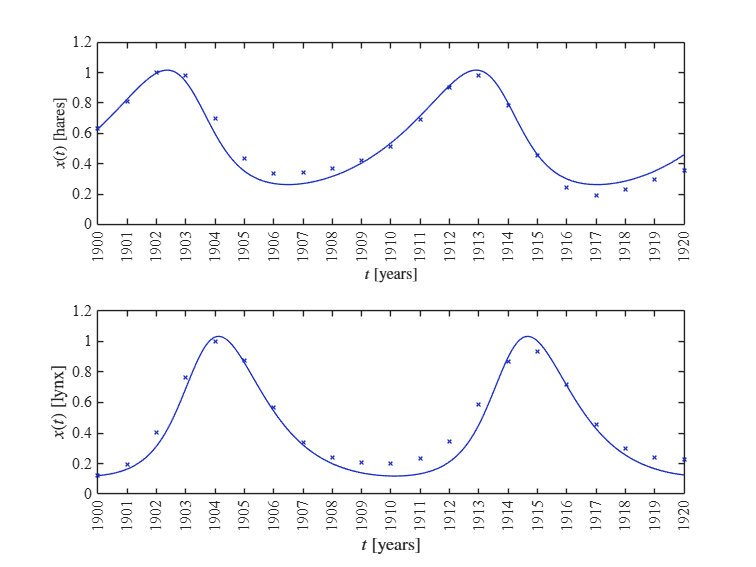

par = table2array(mdl.Coefficients(:,1));
[ta, xa, ya] = LotkaVolterra(par, t, x(1), y(1));
plotfitting(t, x, y, ta, xa, ya, figname, normalize)

## **Soluciones y plano de fase**

%clc; close all; warning('off', 'all')
file = 'data.csv'; smooth = false; normalize = false;
load('parameters.mat');
par = [alpha, beta, delta, gamma]

par =     0.5449    0.0000    0.0000    0.8464


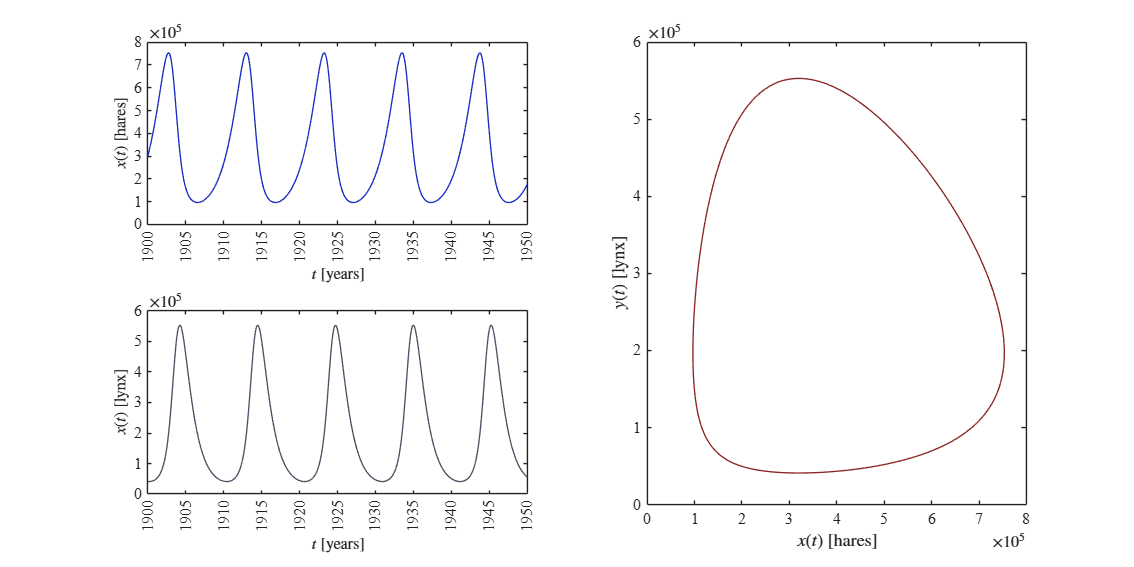

figname = 'Fase';
%plotsys(t,x,y, figname, normalize)
[~, x, y] = getdata(file, smooth, normalize);
tend = 50;
[ta, xa, ya] = LotkaVolterra(par, tend, x(1), y(1));

plotphase(ta, xa, ya,figname)

## Modelo de EDOs con Simulink

clc; clear; close all; warning('off', 'all')
load('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~, x,y] = getdata(file,smooth,normalize);
x0 = x(1); y0 = y(1);
filesim = 'Simulation';
sim(filesim)
parameters.StopTime = '40';
% parameters.MaxStep = '0.1';
set_param('Simulation/alpha', 'Value', num2str(alpha))
set_param('Simulation/beta', 'Value', num2str(beta))
set_param('Simulation/delta', 'Value', num2str(delta))
set_param('Simulation/gamma', 'Value', num2str(gamma))
set_param('Simulation/x0', 'Value', num2str(x0))
set_param('Simulation/y0', 'Value', num2str(y0))

### Funcines ode para ecuaciones stiff

### Funcion ode15s

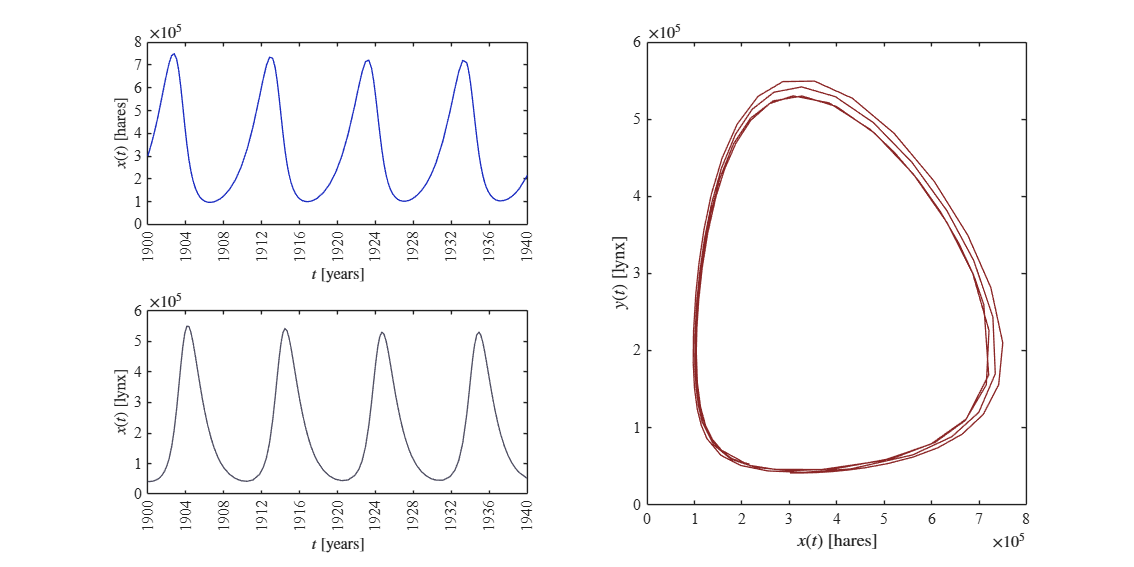

parameters.Solver = 'ode15s';
f = sim(filesim,parameters);
figname = 'simulink_ode15s';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode23s

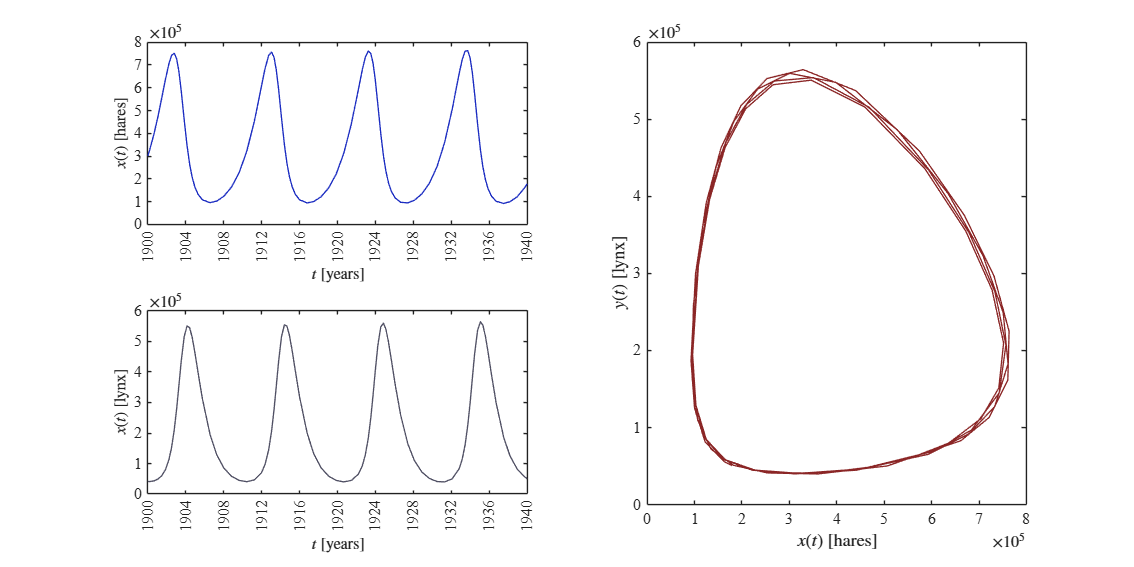

parameters.Solver = 'ode23s';
f = sim(filesim,parameters);
figname = 'simulink_ode23s';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode23t

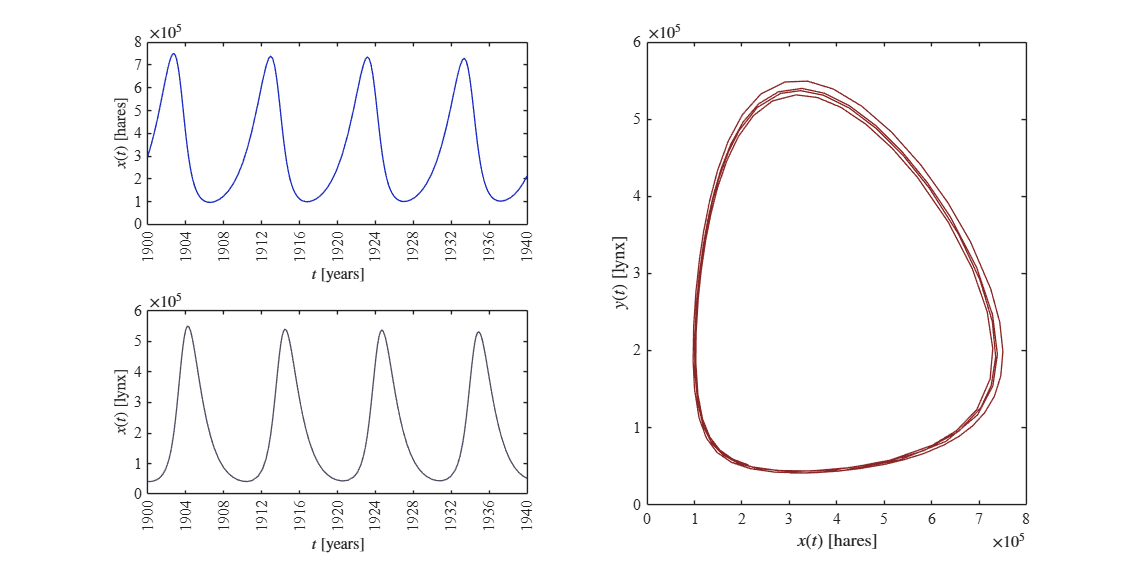

parameters.Solver = 'ode23t';
f = sim(filesim,parameters);
figname = 'simulink_ode23t';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode23tb    

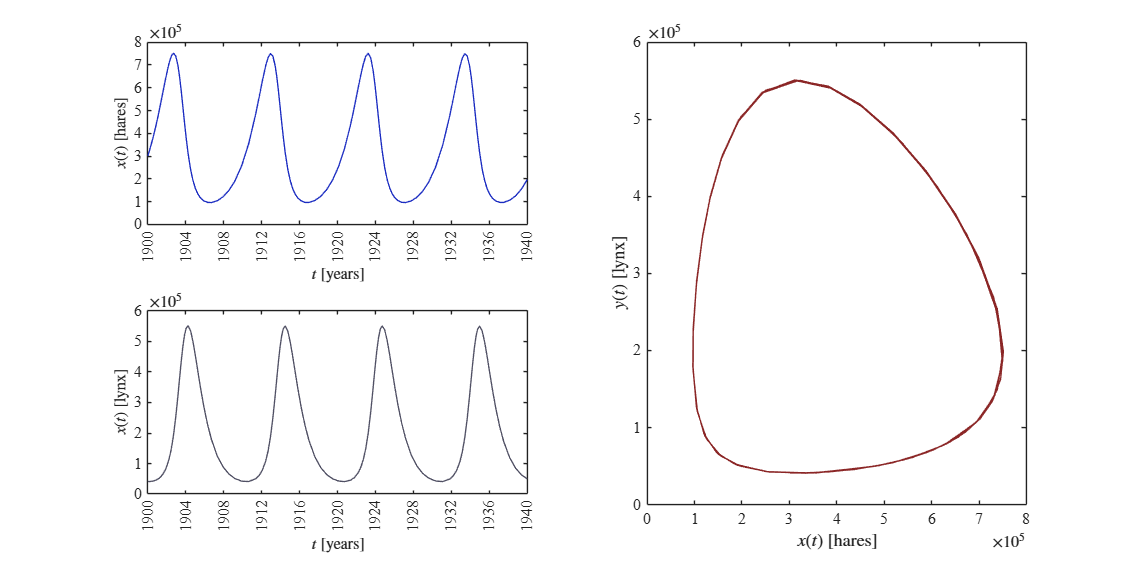

parameters.Solver = 'ode23tb';
f = sim(filesim,parameters);
figname = 'simulink_ode23tb';
plotphase(f.t,f.x,f.y,figname)

### Funcines ode para ecuaciones non-stiff

### Funcion ode45

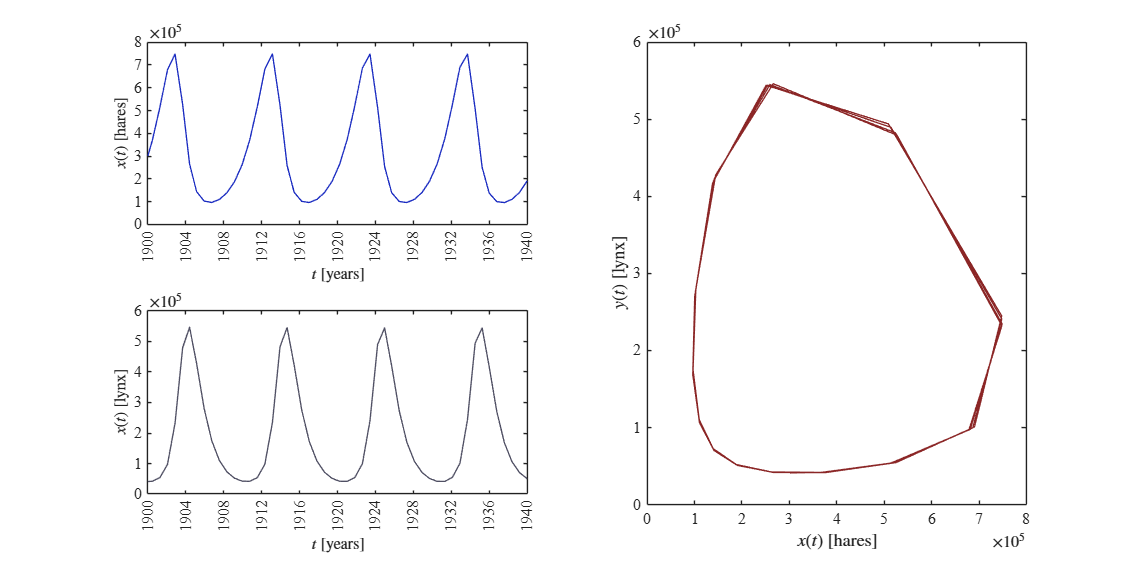

parameters.Solver = 'ode45';
f = sim(filesim,parameters);
figname = 'simulink_ode45s';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode23

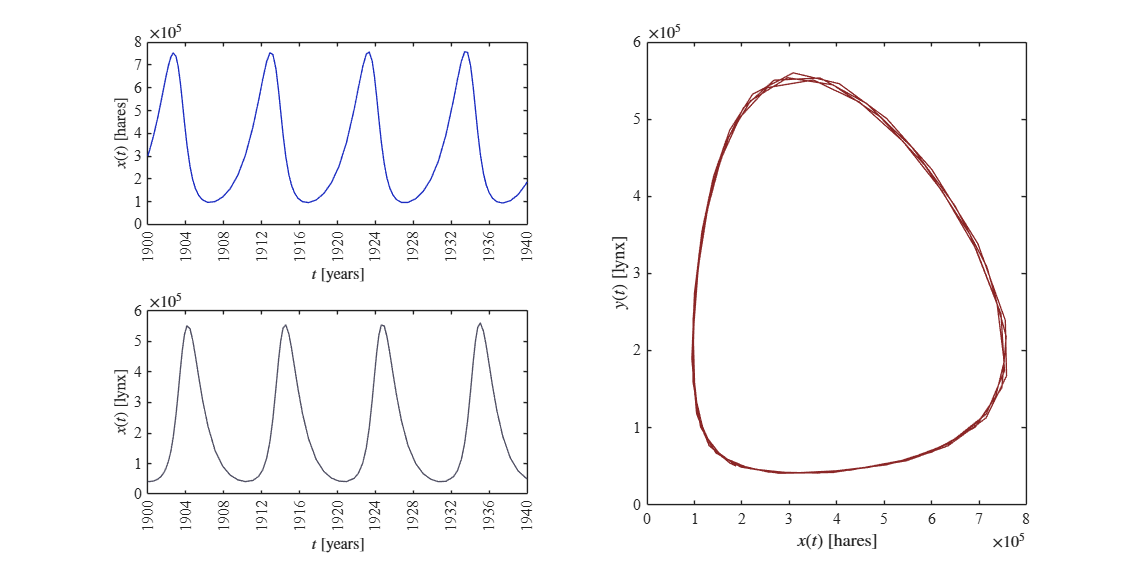

parameters.Solver = 'ode23';
f = sim(filesim,parameters);
figname = 'simulink_ode23';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode113

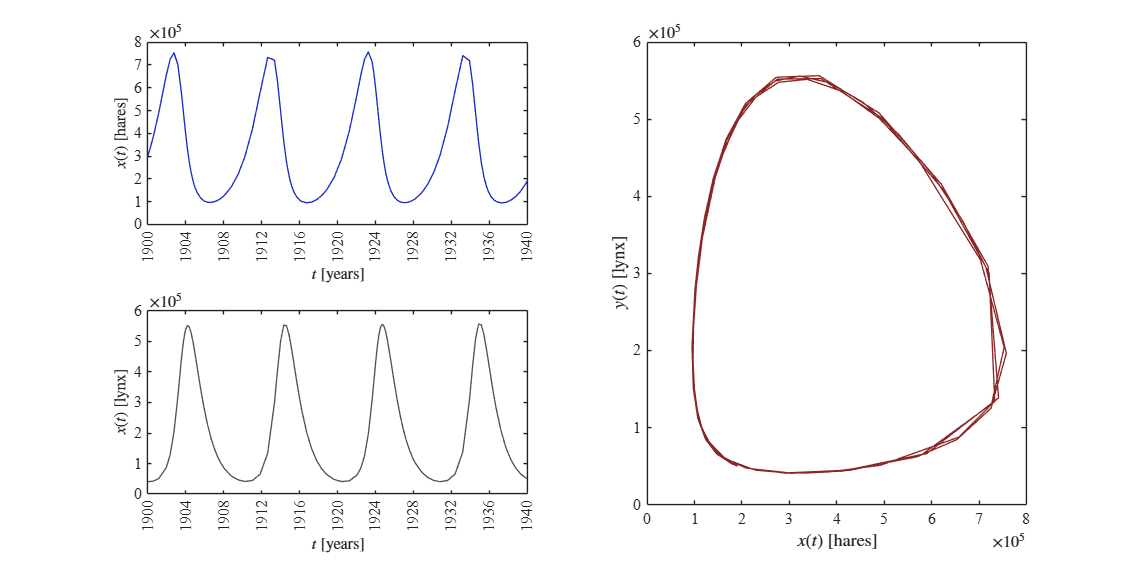

parameters.Solver = 'ode113';
f = sim(filesim,parameters);
figname = 'simulink_ode113';
plotphase(f.t,f.x,f.y,figname)

### Funcines ode con paso de integracion fijo [diferencias finitas]

### Parameters

parameters.FixedStep = "1E-1";

### Funcion ode1

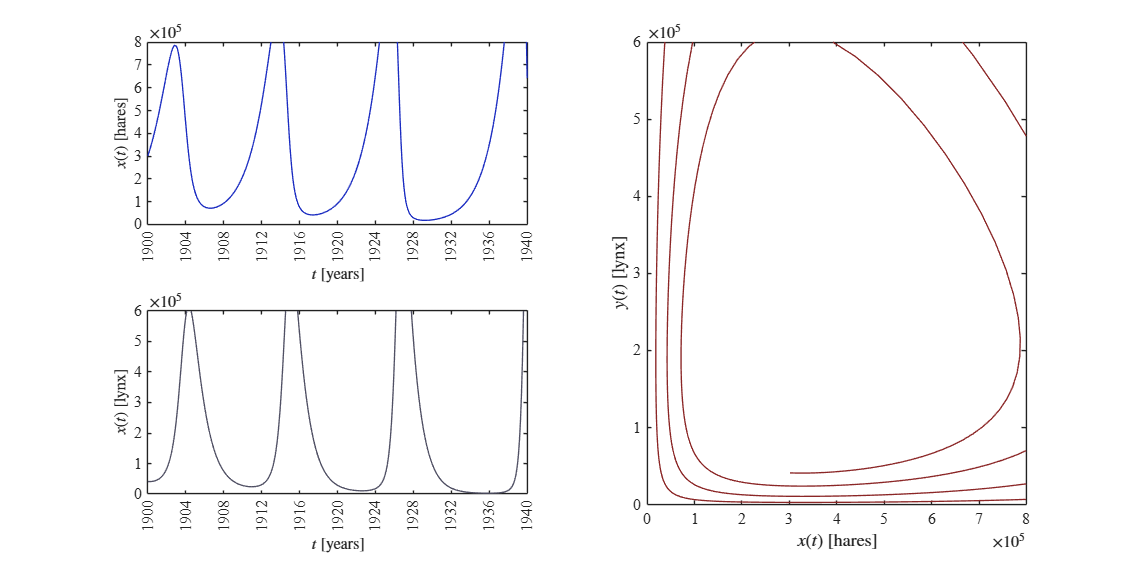

parameters.Solver = 'ode1';
f = sim(filesim,parameters);
figname = 'simulink_ode1';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode2

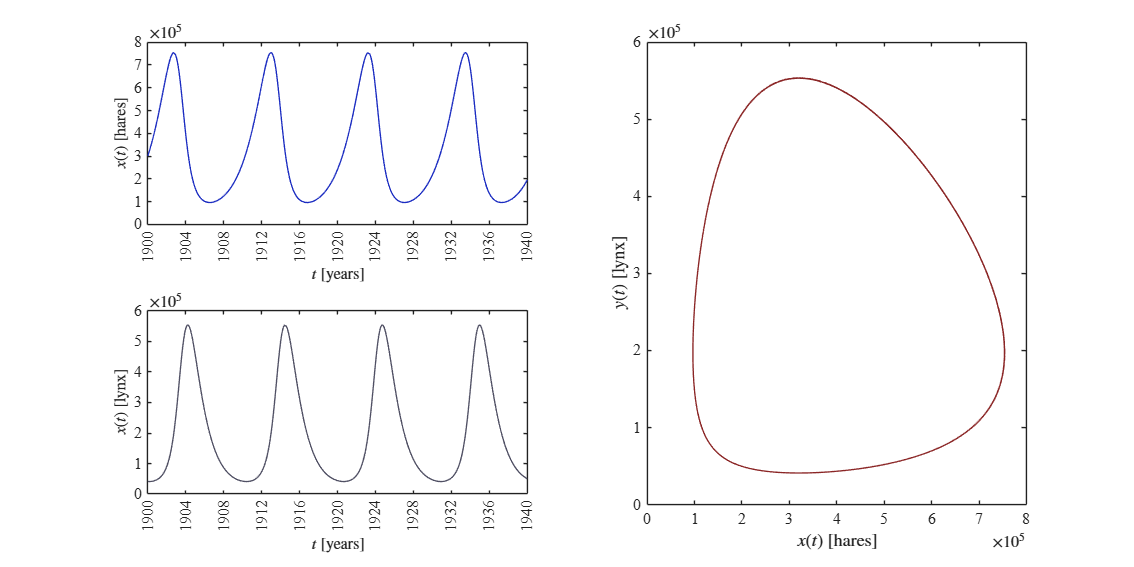

parameters.Solver = 'ode2';
f = sim(filesim,parameters);
figname = 'simulink_ode2';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode3

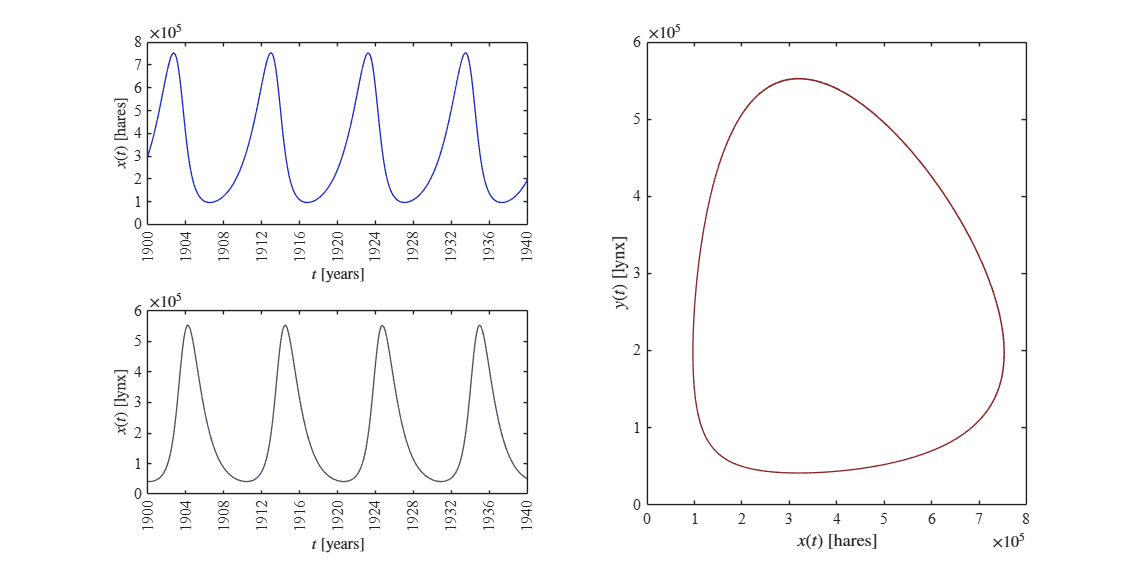

parameters.Solver = 'ode3';
f = sim(filesim,parameters);
figname = 'simulink_ode3';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode4

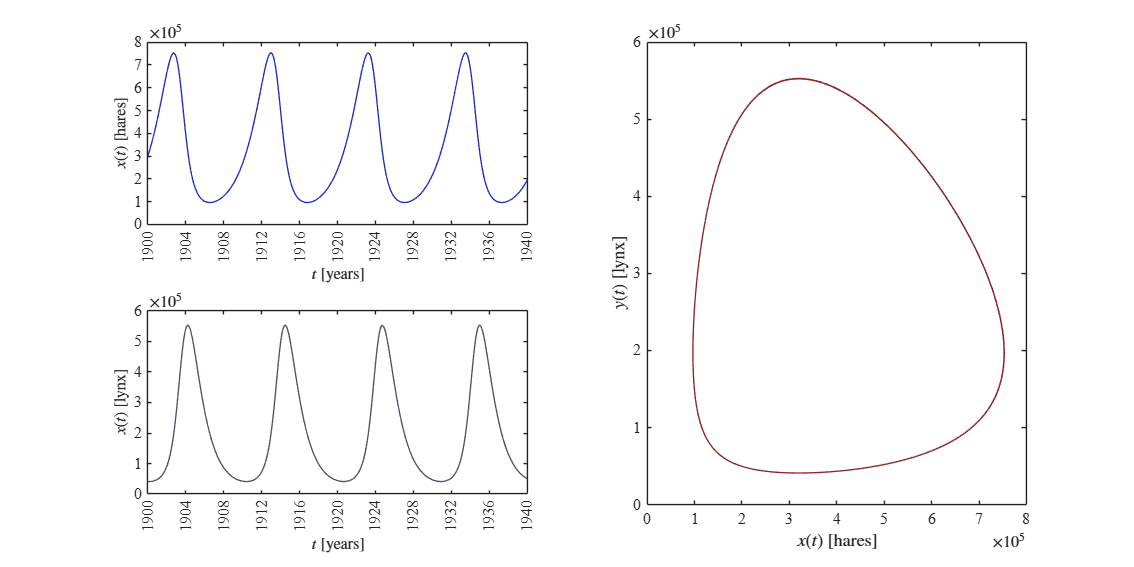

parameters.Solver = 'ode4';
f = sim(filesim,parameters);
figname = 'simulink_ode4';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode5

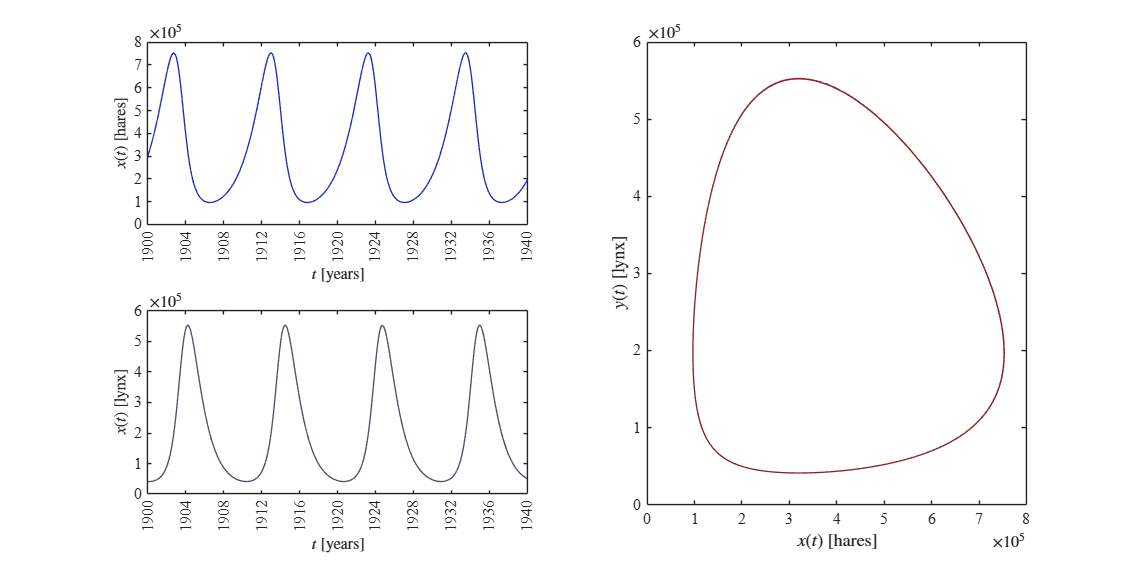

parameters.Solver = 'ode5';
f = sim(filesim,parameters);
figname = 'simulink_ode1';
plotphase(f.t,f.x,f.y,figname)

### Funcion ode seleccionada: ode23tb    

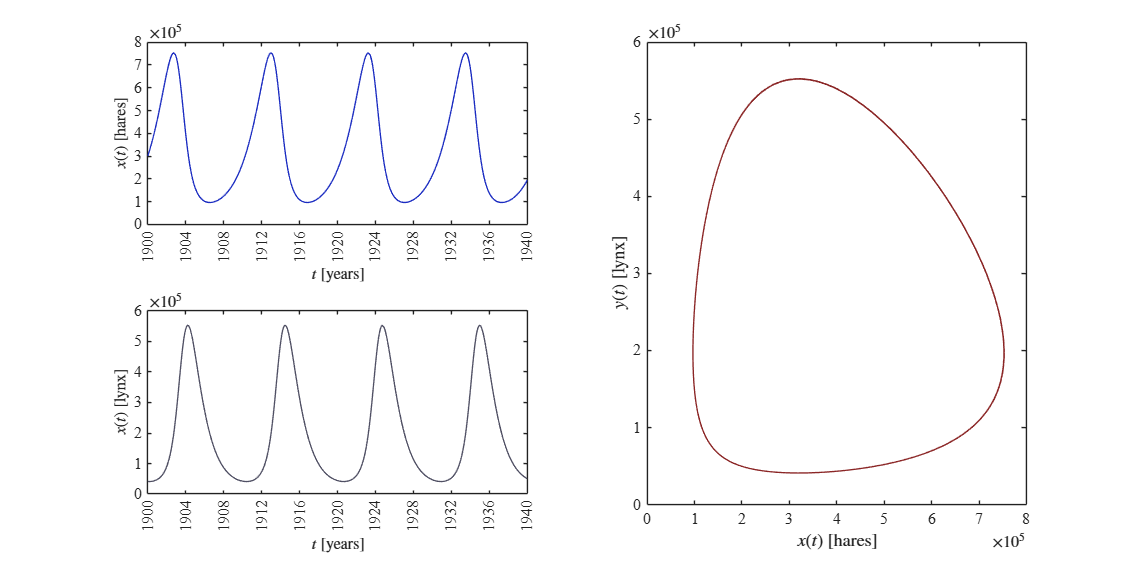

parameters.MaxStep = "0.1";
parameters.Solver = 'ode23tb';
f = sim(filesim,parameters);
figname = 'simulink_ode23tb_dt';
plotphase(f.t,f.x,f.y,figname)

## Funciones anonimas

clc; clear; close all; warning('off', 'all')
load('parameters.mat')
file = 'data.csv'; smooth = false; normalize = false;
[~, x,y] = getdata(file,smooth,normalize);
x0 = x(1); y0 = y(1);
par = [alpha, beta, delta, gamma];

par =     0.5449    0.0000    0.0000    0.8464


### Funcion ode78

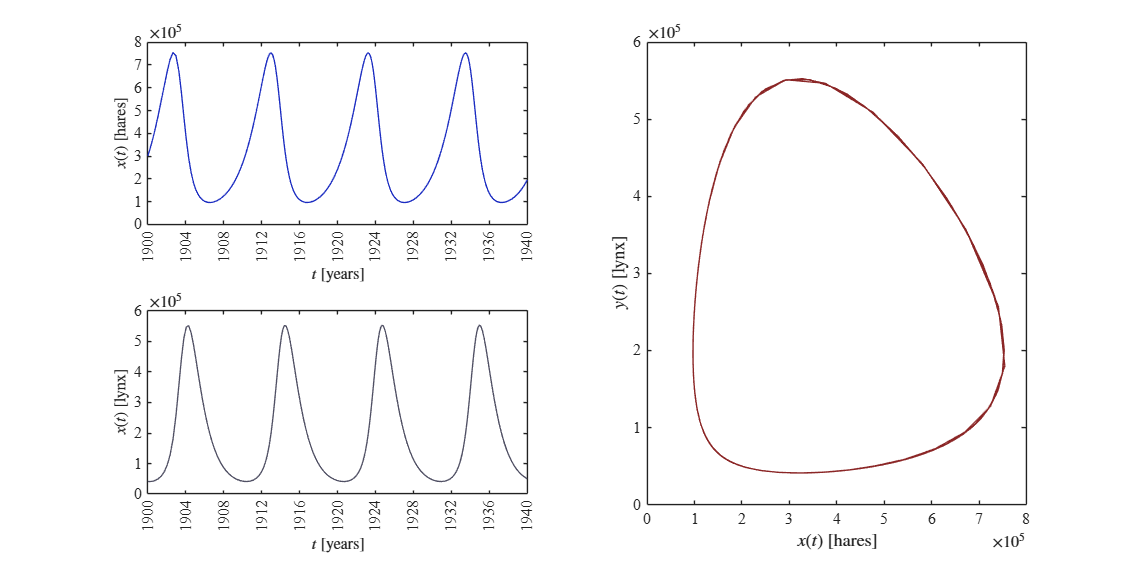

[t, fsol] = ode78(@(t,V) sysODE(V,par),[0,40],[x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'simulink_ode78';
plotphase(t,x,y,figname)

### Funcion ode89

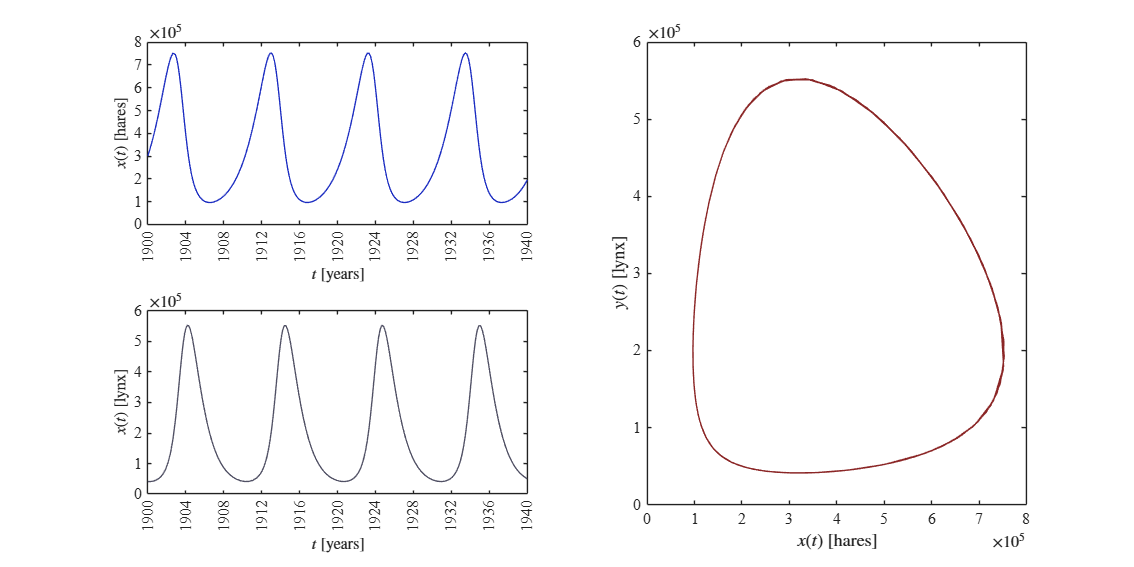

[t, fsol] = ode89(@(t,V) sysODE(V,par),[0,40],[x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'simulink_ode89';
plotphase(t,x,y,figname)

### Funcion con arreglo predefinido del tiempo

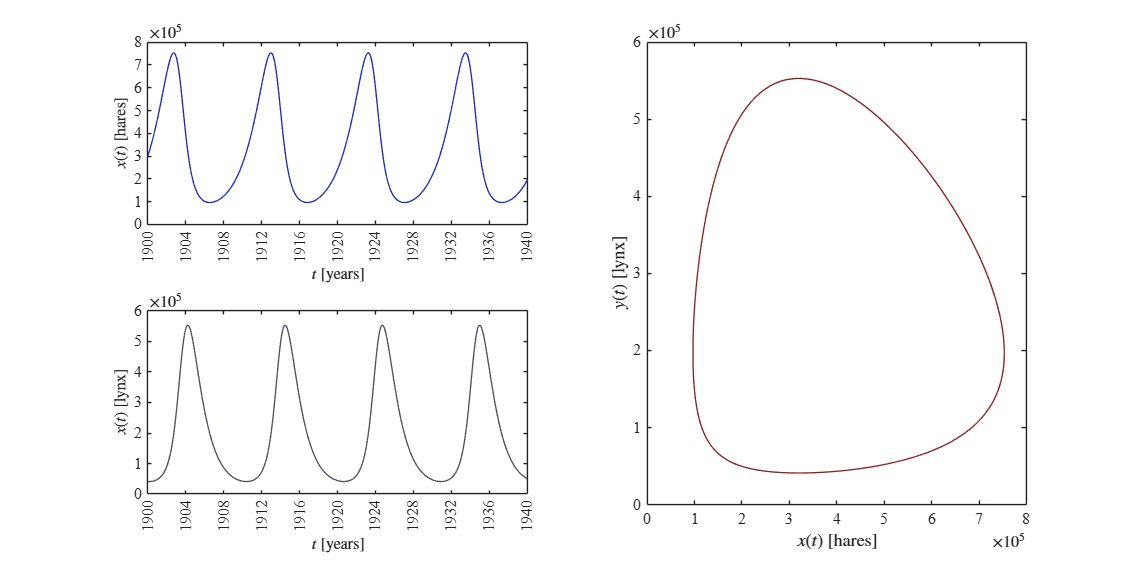

tspan = (0:1E-3:40)';
[t, fsol] = ode89(@(t,V) sysODE(V,par), tspan, [x0,y0]);
x = fsol(:,1);
y = fsol(:,2);
figname = 'simulink_ode89';
plotphase(t,x,y,figname)

## Modelo matematico

function dV = sysODE(V, par) %V(1) = x; V(2) = y
    alpha = par(1); beta = par(2); delta = par(3); gamma = par(4);
    dV = zeros(2,1);
    dV(1) = alpha*V(1) - beta*V(1)*V(2);
    dV(2) = delta*V(1)*V(2) - gamma*V(2); 
end


## **Estabilidad de los equilibrios**

clc; clear; close all; warning('off', 'all')
load('parameters.mat')
clr3 = [139, 38, 38]/255

clr3 =     0.5451    0.1490    0.1490


file = 'data.csv'; smooth = false; normalize = false;
% xe0 = 0; ye0 = 0;


### Condiciones iniciales: origen

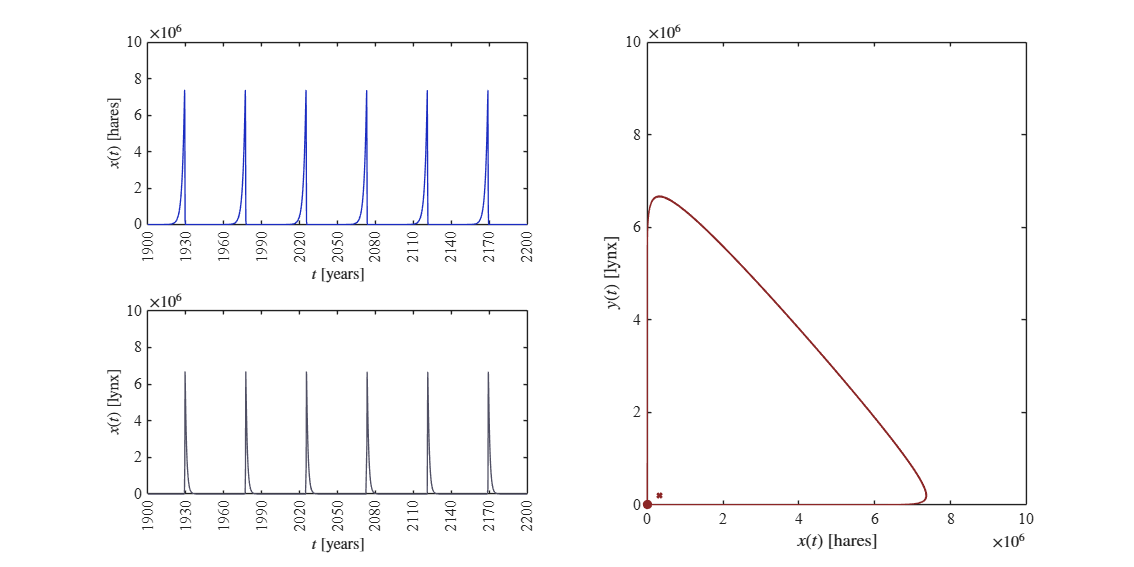

xe0 = 0; ye0 = 0;
xe1 = gamma/delta; ye1 = alpha/beta;
tend = 300;
[t,x,y] = LotkaVolterra([alpha, beta, delta, gamma], tend, 1, 1);
figname = 'eq_origin';
plotphase(t,x,y,figname);...
    subplot(2,2,1); ylim([0 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,3); ylim([-1 1E7]); yticks(0:0.2E7:1E7);...
    subplot(2,2,[2,4]); xlim([0 1E7]); xticks(0:0.2E7:1E7); ylim([0 1E7]); yticks(0:0.2E7:1E7)
    subplot(2,2,[2,4]); plot(xe1, ye1, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(xe0, ye0, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(1, 1, 'o', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)

### Condiciones iniciales: Equilibrio de especies

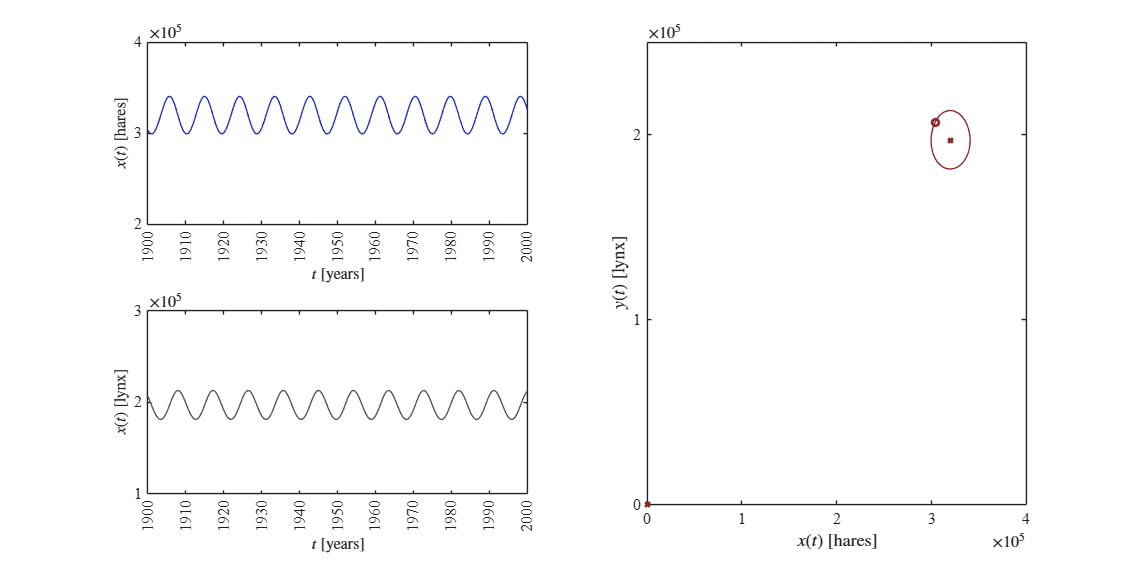

xe0 = 0; ye0 = 0;
xe1 = gamma/delta; ye1 = alpha/beta;
tend = 100;
[t,x,y] = LotkaVolterra([alpha, beta, delta, gamma], tend, 0.95*xe1, 1.05*ye1);
figname = 'eq_origin1.5xe-0.5ye';
plotphase(t,x,y,figname);...
    subplot(2,2,1); ylim([2E5 4E5]); %yticks(2:0.2E7:1E7);...
    subplot(2,2,3); ylim([1E5 3E5]); %yticks(0:0.2E7:1E7);...
    subplot(2,2,[2,4]); xlim([0 4E5]); ylim([0 2.5E5]);...
    subplot(2,2,[2,4]); plot(xe1, ye1, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(xe0, ye0, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(0.95*xe1, 1.05*ye1, 'o', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)

### Condiciones iniciales: Equilibrio de especies

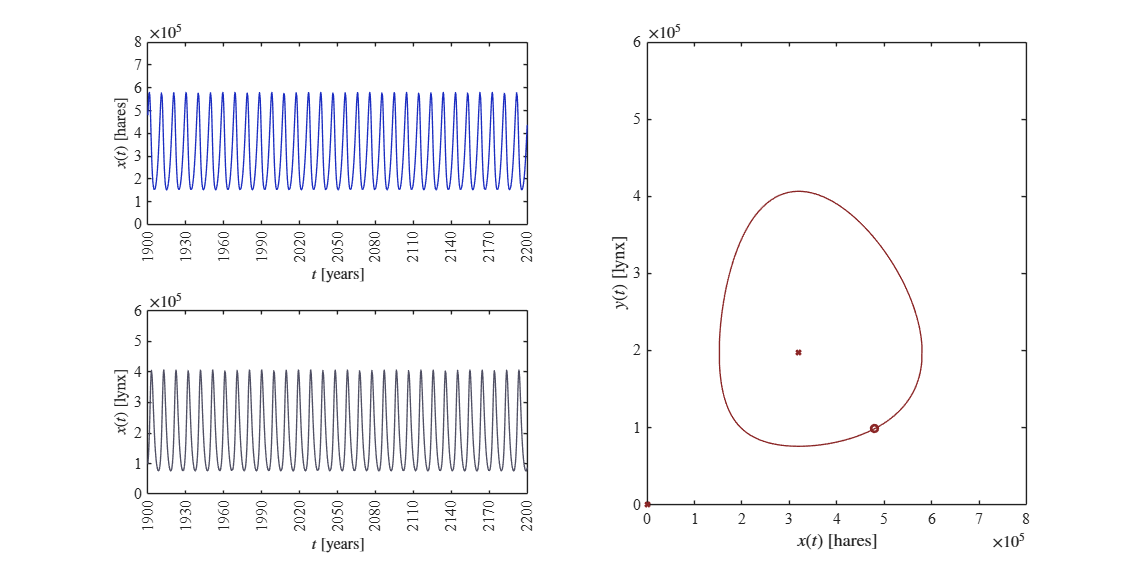

    xe0 = 0; ye0 = 0;
    xe1 = gamma/delta; ye1 = alpha/beta;
    tend = 300;
    [t,x,y] = LotkaVolterra([alpha, beta, delta, gamma], tend, 1.5*xe1, 0.5*ye1);
    figname = 'eq_origin1.5xe-0.5ye';
    plotphase(t,x,y,figname);...
        %subplot(2,2,1); ylim([0 1E7]); yticks(0:0.2E7:1E7);...
    %subplot(2,2,3); ylim([-1 1E7]); yticks(0:0.2E7:1E7);...
    %subplot(2,2,[2,4]); xlim([0 1E7]); xticks(0:0.2E7:1E7); ylim([0 1E7]); yticks(0:0.2E7:1E7)
    subplot(2,2,[2,4]); plot(xe1, ye1, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(xe0, ye0, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(1.5*xe1, 0.5*ye1, 'o', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)

### Condiciones iniciales: Alejado del equilibrio

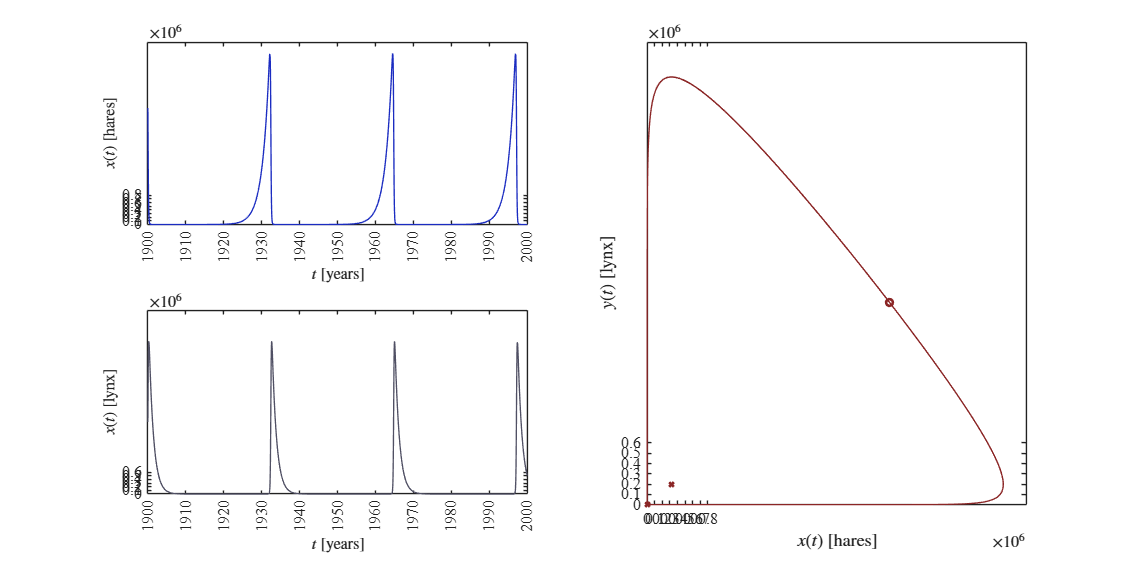

    xe0 = 0; ye0 = 0;
    xe1 = gamma/delta; ye1 = alpha/beta;
    tend = 100;
    [t,x,y] = LotkaVolterra([alpha, beta, delta, gamma], tend, 10*xe1, 10*ye1);
    figname = 'eq_origin1000xe-1000ye';
    plotphase(t,x,y,figname);...
        %subplot(2,2,1); ylim([0 1E7]); yticks(0:0.2E7:1E7);...
    %subplot(2,2,3); ylim([-1 1E7]); yticks(0:0.2E7:1E7);...
    %subplot(2,2,[2,4]); xlim([0 1E7]); xticks(0:0.2E7:1E7); ylim([0 1E7]); yticks(0:0.2E7:1E7)
    subplot(2,2,[2,4]); plot(xe1, ye1, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(xe0, ye0, 'x', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)
    subplot(2,2,[2,4]); plot(10*xe1, 10*ye1, 'o', 'linewidth', 2, 'MarkerSize', 5,'Color',clr3)

## **Funciones**

function [to, xo, yo] = getdata(file, smooth, normalize)
    sys = readmatrix(file);
    to = round(sys(:,1));
    xo = sys(:,2)*1E4;
    yo = sys(:,3)*1E4;
    to = to - to(1); % t = [0, 20] para el ajuste de las ecuaciones diferenciales
    if smooth == false && normalize == false
        return
    elseif smooth == true && normalize == false
        xo = smoothdata(xo, 'gaussian', 5);
        yo = smoothdata(yo, 'gaussian', 5);
        return
    elseif smooth == false && normalize == true
        xo = xo / max(xo);
        yo = yo / max(yo);
    elseif smooth == true && normalize == true
        xo = smoothdata(xo, 'gaussian', 5);
        yo = smoothdata(yo, 'gaussian', 5);
        xo = xo / max(xo);
        yo = yo / max(yo);
    end
    
end

function plotsys(t, x, y, figname, normalize)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1,1, 20, 15])
    fs = 12; clr1 = [27, 44, 193]/255; clr2 = [27, 44, 193]/255; 

    subplot(2,1,1); hold on; box on; grid off; fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
    plot(t + 1900, x, 'x', 'linewidth', 1, 'MarkerSize', 4, 'color', clr1)
    xlabel('$t$ [years]', 'Interpreter', 'latex')
    ylabel('$x(t)$ [hares]', 'Interpreter', 'latex')
    if normalize == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif normalize == false
        ylim([0 10] * 1E5); yticks(0:2E5:10E5)
    end
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)

    subplot(2,1,2); hold on; box on; grid off;  fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
    plot(t + 1900, y, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', clr2)
    xlabel('$t$ [years]', 'Interpreter', 'latex')
    ylabel('$x(t)$ [lynx]', 'Interpreter', 'latex')
    if normalize == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif normalize == false
        ylim([0 10] * 1E5); yticks(0:2E5:10E5)
    end
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)

    exportgraphics(gcf, [figname, '.pdf'], 'ContentType', 'vector')
end

function mdl = fitmodel(to, xo, yo, p0, biostats)
    x0 = xo(1); y0 = yo(1);
    to = [to; to];
    fo = [xo; yo];

    function fa = model(p0, to)
        alpha = p0(1); beta = p0(2);
        delta = p0(3); gamma = p0(4);
        dt = 1e-2;
        time = (0:dt:max(to))';
        x = zeros(length(time), 1); x(1) = x0;
        y = zeros(length(time), 1); y(1) = y0;
        n = round(max(to)/dt);

        for i = 1:n %Metodo de Heun (Euler mejorado)
            [fx, fy] = f(x(i), y(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            [fxn, fyn] = f(xn, yn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
        end

        function [dx, dy] = f(x,y)
            dx = alpha*x - beta*x*y;
            dy = delta*x*y - gamma*y;
        end

        ta = reshape(to, [], 2);
        xa = interp1(time, x, ta(:,1), 'linear');
        ya = interp1(time, y, ta(:,1), 'linear');
        fa = [xa;ya];
        
    end

    mdl = fitnlm(to, fo, @model, p0);
    
    if biostats == true
        Estimate = table2array(mdl.Coefficients(:,1));
        SE = table2array(mdl.Coefficients(:,2));
        Pvalue = table2array(mdl.Coefficients(:,4));
        alfa = 0.05;
        CI95 = coefCI(mdl,alfa);
        dof = mdl.DFE;
        tval = tinv(1-alfa/2, dof);
        MoE = SE * tval;
        Parameters = {"alfa"; "beta"; "delta"; "gamma"};
        R2a = mdl.Rsquared.Adjusted;
        RSS = mdl.SSE;
        AICc = mdl.ModelCriterion.AICc;
        Results = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
        fprintf('\n-----Bioestadisticos-----')
        fprintf('\nCantidad de datos: %.f', numel(fo));
        fprintf('\nCatidad de parametros: %.f', numel(Estimate));
        fprintf('\nGrados de libertad: %.f', dof);
        fprintf('\nValor t-student: %.3f', tval);
        fprintf('\nValor de significancia (alfa) para los intervalos de confianza: %.2f', alfa);
        fprintf('\n\nRelacion n/k<40 para el calculo del AICc: %.3f\n\n', numel(fo)/numel(Estimate));
        disp(Results)
        fprintf('\n-----Criterios de bondad de ajuste-----')
        fprintf('\nR cuadrada ajustada: %.3f',R2a)
        fprintf('\nSuma residual de cuadrados (RSS): %.3f', RSS)
        fprintf('\nCriterio de informacion de Akaike corregido: %.3f', AICc)
    end
end

function plotfitting(t, x, y, ta, xa, ya, figname, normalize)
    set(figure(), 'color', 'w')
    set(gcf, 'units', 'centimeters', 'position', [1,1, 20, 15])
    fs = 12; clr1 = [27, 44, 193]/255; clr2 = [27, 44, 193]/255;

    subplot(2,1,1); hold on; box on; grid off; fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
    plot(t + 1900, x, 'x', 'linewidth', 1, 'MarkerSize', 4, 'color', clr1)
    plot(ta + 1900, xa, '-', 'linewidth', 1, 'MarkerSize', 4, 'color', clr2)
    xlabel('$t$ [years]', 'Interpreter', 'latex')
    ylabel('$x(t)$ [hares]', 'Interpreter', 'latex')
    if normalize == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif normalize == false
        ylim([0 10] * 1E5); yticks(0:2E5:10E5)
    end
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)

    subplot(2,1,2); hold on; box on; grid off;  fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
    plot(t + 1900, y, 'x', 'LineWidth', 1, 'MarkerSize', 4, 'Color', clr1)
    plot(ta + 1900, ya, '-', 'LineWidth', 1, 'MarkerSize', 4, 'Color', clr2)
    xlabel('$t$ [years]', 'Interpreter', 'latex')
    ylabel('$x(t)$ [lynx]', 'Interpreter', 'latex')
    if normalize == true
        ylim([0 1.2]); yticks(0:0.2:1.2)
    elseif normalize == false
        ylim([0 10] * 1E5); yticks(0:2E5:10E5)
   end
    xlim([1900 1920]); xticks(1900:1:1920); xtickangle(90)
    exportgraphics(gcf, [figname, '.pdf'], 'ContentType', 'vector')
end

function [time, x, y] = LotkaVolterra(p0, to, x0, y0)
    alpha = p0(1); beta = p0(2);
    delta = p0(3); gamma = p0(4);
    dt = 1e-2;
    time = (0:dt:max(to))';
    x = zeros(length(time), 1); x(1) = x0;
    y = zeros(length(time), 1); y(1) = y0;
    n = round(max(to)/dt);
    for i = 1:n %Metodo de Heun (Euler mejorado)
        [fx, fy] = f(x(i), y(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        [fxn, fyn] = f(xn, yn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
    end

    function [dx, dy] = f(x,y)
        dx = alpha*x - beta*x*y;
        dy = delta*x*y - gamma*y;
    end
end

function plotphase(t, x, y, figname)
set(figure(), 'color', 'w')
set(gcf, 'units', 'centimeters', 'position', [1,1, 30, 15])
fs = 12; clr1 = [27, 44, 193]/255; clr2 = [80, 80, 100]/255; clr3 = [139, 38, 38]/255;

subplot(2,2,1); hold on; box on; grid off; fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
plot(t + 1900, x, '-', 'linewidth', 1, 'Color', clr1)
xlabel('$t$ [years]', 'Interpreter', 'latex')
ylabel('$x(t)$ [hares]', 'Interpreter', 'latex')
 yticks(0:1E5:8E5); %ylim([0 8] * 1E5);
xlim([1900 1900+max(t)]); xticks(1900:max(t)/10:1900+max(t)); xtickangle(90)

subplot(2,2,3); hold on; box on; grid off;  fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
plot(t + 1900, y, '-', 'LineWidth', 1, 'Color', clr2)
xlabel('$t$ [years]', 'Interpreter', 'latex')
ylabel('$x(t)$ [lynx]', 'Interpreter', 'latex')
 yticks(0:1E5:6E5); %ylim([0 6] * 1E5);
xlim([1900 1900+max(t)]); xticks(1900:max(t)/10:1900+max(t)); xtickangle(90)

subplot(2,2,[2 4]); hold on; box on; grid off;  fontsize(fs, 'points'); set(gca, 'fontname', 'timesnewroman')
plot(x,y, '-', 'LineWidth', 1, 'Color', clr3)
xlabel('$x(t)$ [hares]', 'Interpreter', 'latex')
ylabel('$y(t)$ [lynx]', 'Interpreter', 'latex')
 yticks(0:1E5:6E5); %ylim([0 6] * 1E5);
 xticks(0:1E5:8E5); %xlim([0 8] * 1E5);

exportgraphics(gcf, [figname, '.pdf'], 'ContentType', 'vector')
end
